# Attacking Subsystem- Performance Evaluation for spoofing target accuracy

## Initialize the Evaluation Script

clear;
c = clock;
seed = floor(sum(c));
rng(seed);
kristen_path = "C:\Users\krist\OneDrive\Documents\2022-2023 School Year\Radar Security Project\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
windows_file_path = "C:\Users\Operator\Documents\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
david_path = "/home/david/Documents/BlackBoxRadarAttacks/MATLAB/config_files/";
file_path = "20MHz_USRP_500us.json";

%set the configuration path
config_path = david_path + file_path;

### Generate Test Ranges and Velocities

valid_ranges = [60,200];
valid_velocities = [-25,25];
num_cases = 100;

[spoof_ranges,spoof_velocities] = characterization_functions.initialize_USRP_attack_subsystem_test_cases( ...
                num_cases, ...
                valid_ranges, ...
                valid_velocities);

### Save data needed by the USRP to a file

%save the chirp to a file
characterization_functions.save_USRP_attack_subsystem_chirp_to_file( ...
    config_path);

velocity_file_path = "/home/david/Documents/MATLAB_generated/MATLAB_desired_spoof_velocities/";
range_file_path = "/home/david/Documents/MATLAB_generated/MATLAB_desired_spoof_ranges/";

characterization_functions.save_desired_spoofing_ranges_and_velocities_to_file( ...
    spoof_velocities,...
    velocity_file_path, ...
    spoof_ranges,...
    range_file_path)

## Run Evaluation on USRP

### Process the received data

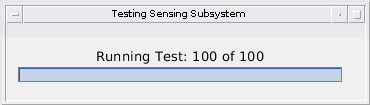

test_data_spoofing_performance =    86.4208   12.3054  178.0938    0.0411   91.6730   12.2643
   86.4208   12.3054  175.9000    0.0452   89.4792   12.2602
   86.4208   12.3054  175.7930    0.0451   89.3722   12.2603
   86.4208   12.3054  176.3083    0.0286   89.8875   12.2768
   86.4208   12.3054  186.4928   -0.0109  100.0720   12.3164
   86.4208   12.3054  176.3220    0.0503   89.9012   12.2552
   86.4208   12.3054  176.7734    0.0188   90.3526   12.2866
   86.4208   12.3054  176.6907    0.0168   90.2699   12.2887
   86.4208   12.3054  176.2482    0.0337   89.8274   12.2717
   86.4208   12.3054  175.3454    0.0237   88.9246   12.2817


save_file_name = "attack_subsystem_spoofing_performance";
frames_to_compute = 40;
attack_start_frame = 11;
num_attack_frames = 15;

test_data_spoofing_performance = ...
                characterization_functions.USRP_get_spoofing_test_results( ...
                    num_cases, ...
                    frames_to_compute, ...
                    attack_start_frame, ...
                    num_attack_frames, ...
                    spoof_ranges, ...
                    spoof_velocities, ...
                    config_path, ...
                    save_file_name)

### Plot Test Case Information

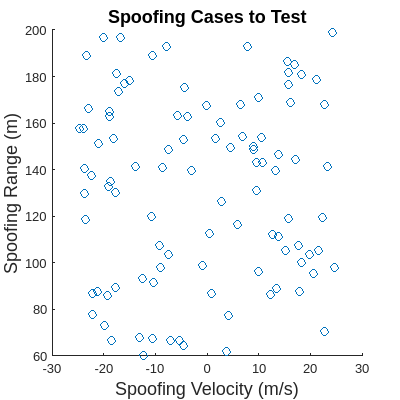

read_file_name = save_file_name + ".csv";
characterization_functions.plot_spoofing_test_configurations(read_file_name);

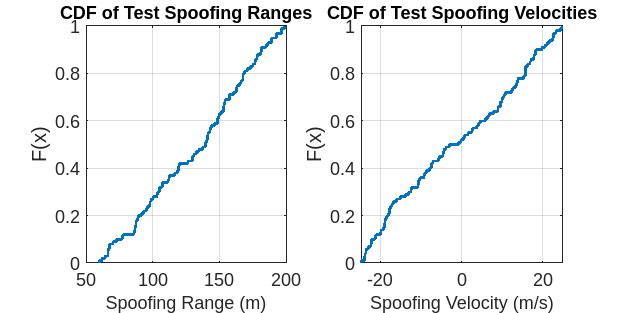

characterization_functions.plot_spoofing_test_configuration_cdfs(read_file_name);

### Plot Test Case Results

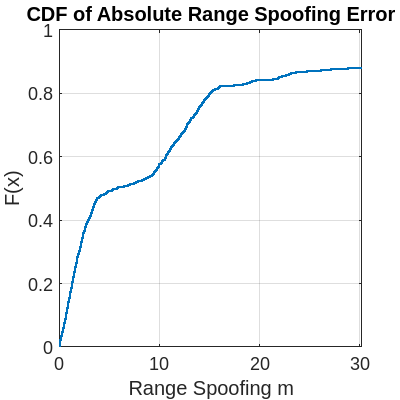

ans = 1×5 table
    Mean (m)    Variance (m)^2    MSE (m)^2    80th Percentile (m)    Percent Failed Trials
    ________    ______________    _________    ___________________    _____________________

     14.541         711.52         922.49            15.106                     0          


% plot Range Spoofing Error
actual_values_idx = 1;
estimated_values_idx = 3;
abs_errors_idx = 5;
metric_title = "Range Spoofing";
metric_units = "m";
percentile = 80;
scale_factor = 1;
characterization_functions.generate_testing_summary_absolute_error(read_file_name,...
    actual_values_idx, ...
    estimated_values_idx, ...
    abs_errors_idx, ...
    metric_title, ...
    metric_units,...
    percentile,...
    scale_factor)

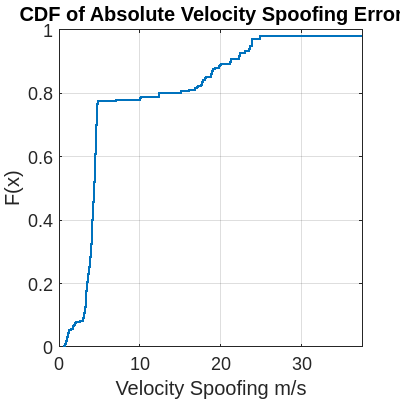

ans = 1×5 table
    Mean (m/s)    Variance (m/s)^2    MSE (m/s)^2    85th Percentile (m/s)    Percent Failed Trials
    __________    ________________    ___________    _____________________    _____________________

      8.9158           214.49           293.84               18.71                      0          


%Summary of Spoofing Velocity Performance
actual_values_idx = 2;
estimated_values_idx = 4;
abs_errors_idx = 6;
metric_title = "Velocity Spoofing";
metric_units = "m/s";
percentile = 85;
scale_factor = 1;
characterization_functions.generate_testing_summary_absolute_error(read_file_name,...
    actual_values_idx, ...
    estimated_values_idx, ...
    abs_errors_idx, ...
    metric_title, ...
    metric_units,...
    percentile,...
    scale_factor)